clear all, close all;
addpath('..\');


%SAMPLING_FREQ = (50*16*16);
SAMPLING_FREQ = 10^8;
BUFFER_LEN = 2048;
SIM_TIME = 12*BUFFER_LEN/SAMPLING_FREQ

SIM_TIME = 2.4576e-04

FREQ = SAMPLING_FREQ*(0 : BUFFER_LEN-1)/BUFFER_LEN;
MAIN_FREQ_INDEX = 9;
csv_read;

out = sim("hdl_model.slx")

out =   Simulink.SimulationOutput:

                   tout: [43009x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim_FFT = out.yout{1}.Values;
sim_RMS = out.yout{2}.Values;
sim_MAX = out.yout{3}.Values;
sim_MIN = out.yout{4}.Values;
sim_THD = out.yout{5}.Values;


floating_title = "Wyniki symulacji stałoprzecinkowej: "

floating_title = "Wyniki symulacji floating point: "

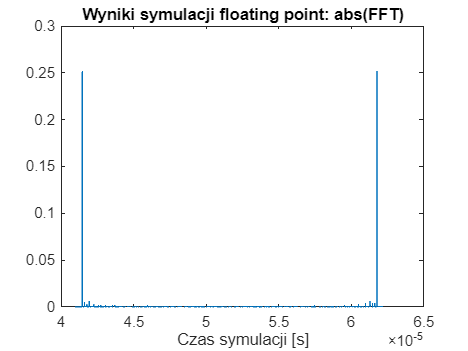


figure;
plot(sim_FFT.Time(2*BUFFER_LEN:3*BUFFER_LEN+80, :), abs(sim_FFT.Data(2*BUFFER_LEN:3*BUFFER_LEN+80, :)));
title(floating_title + "abs(FFT)")
xlabel("Czas symulacji [s]")

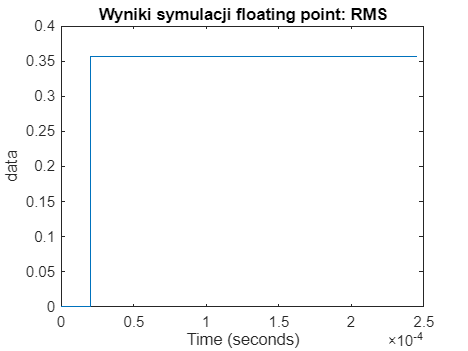


figure;
plot(sim_RMS);
title(floating_title + "RMS")

disp(sim_RMS.Data(end, end))

    0.3562



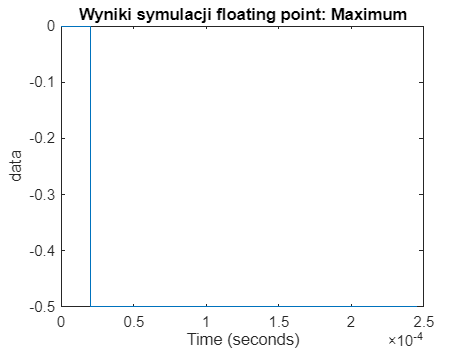


figure;
plot(sim_MAX);
title(floating_title + "Maximum")

disp(sim_MAX.Data(end, end))

   -0.4991



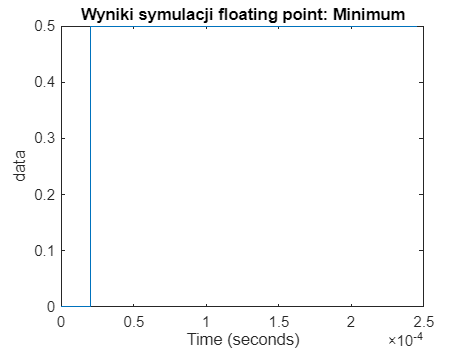


figure;
plot(sim_MIN);
title(floating_title + "Minimum")

disp(sim_MIN.Data(end, end))

    0.4994



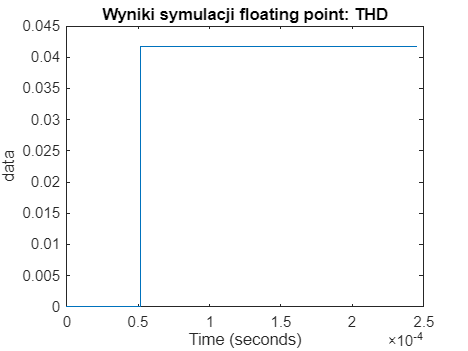


figure;
plot(sim_THD);
title(floating_title + "THD")

disp(sim_THD.Data(end, end))

    0.0417

